% Define el nombre del archivo G-code
nombreArchivo = 'barrido_altavoz.gcode'; %Introducir el nombre de la trayectora que se quiera ejecutar

% Configuración del puerto serie
port = 'COM8';  %Introducir puerto correspondiente a donde se conecta el equipo
baudrate = 115200;  % Velocidad de transmisión en baudios
ser = serialport(port, baudrate);
fopen(ser);

recorder1 = audiorecorder(44100,16,1,1);

%Lectura del fichero de instrucciones

instrucciones = char(lectura(nombreArchivo))

% Envio de la trayectoria, captura de la grabación y datos de la posición

[salida] = trayectoria_grabacion2(ser,instrucciones,recorder1);

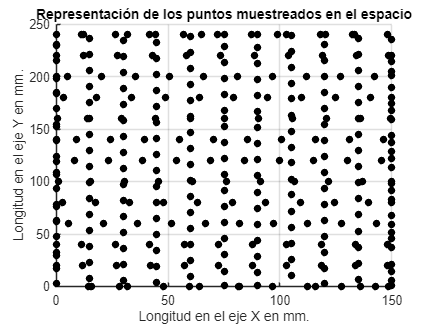

%Representación de la trayectoria 

scatter(salida(:,1),salida(:,2),'k','filled')
grid on
xlabel("Longitud en el eje X en mm.")
ylabel("Longitud en el eje Y en mm.")
title("Representación de los puntos muestreados en el espacio")

%Cálculo de la distancia entre los puntos capturados

for z=1:length(salida)-1
    distancia_puntos(z)=sqrt((abs(salida(1+z,1))-abs(salida(z,1)))^2+((abs(salida(1+z,2))-abs(salida(z,2)))^2));
end

%Cargar archivo grabado y procesado

[signal, Fs] = audioread("altavoz_4000hz.wav");
[samples, channels] = size(signal);
time = linspace(0,samples/Fs,samples);
signal = abs(signal);
muestras_original = 1:samples;

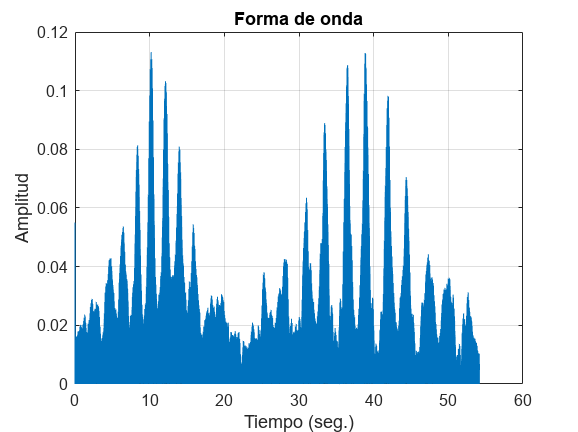

%Forma de onda de la señal grabada

plot(time,signal)
grid on 
title ("Forma de onda")
xlabel("Tiempo (seg.)")
ylabel("Amplitud")

pref = 10^-12;

% Calcular la potencia de la señal en unidades lineales
potencia_lineal = signal.^2;

muestra_anterior = 0;
fin_anterior = 0;

A_db = zeros(1,length(distancia_puntos));
for m = 1:length(distancia_puntos)   

    vel_media = ((salida(m,3)+salida(m+1,3))/(2)); % Cálculo de la velocidad media

    if vel_media == 0

        tiempo_trayectoria = 0;
    else
        tiempo_trayectoria = (distancia_puntos(m))/(((salida(m,3)+salida(m+1,3))/(2))/60); % multiplicamos por 60 para pasar la velocidad de mm/min a mm/seg
    end

    ventana =  floor(Fs*tiempo_trayectoria); % Tamaño de la ventana
    inicio = fin_anterior + 1; % Muestra de inicio de la ventana
    fin = ventana + fin_anterior; % Muestra de final de la ventana

    muestras = signal(inicio:fin);
    media_amplitud = (rms(muestras)); % Media rms de la ventana

    muestra_anterior = ventana;
    fin_anterior = fin;

    A_lineal(m) = media_amplitud;

end

pot_lineal = A_lineal.^2;
A_db = 10*log10(pot_lineal./pref);

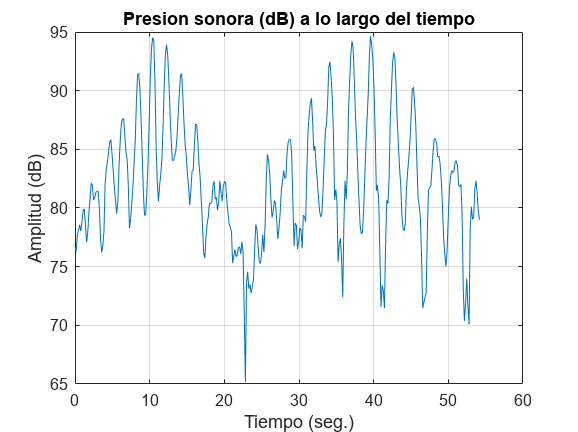

% Representación de los dB a lo largo del tiempo

t = linspace(0,samples/Fs,length(A_db));

figure
plot(t,A_db-2.5)
grid on 
title("Presion sonora (dB) a lo largo del tiempo")
grid on
xlabel("Tiempo (seg.)")
ylabel("Amplitud (dB)")

%Cálculo del tamaño de la matriz de datos

max_pos = max(salida, [], 1);
matriz_size_x = floor(max_pos(1) / max(distancia_puntos)) ; 
matriz_size_y = floor(max_pos(2) / max(distancia_puntos)) ; 

%Declaración de ejes para las representaciones espaciales

eje_x = linspace(0,max_pos(1),length(A_db));
eje_y = linspace(0,max_pos(2),length(A_db));

%Creación del mallado 

[Xq, Yq] = meshgrid(eje_x, eje_y); 

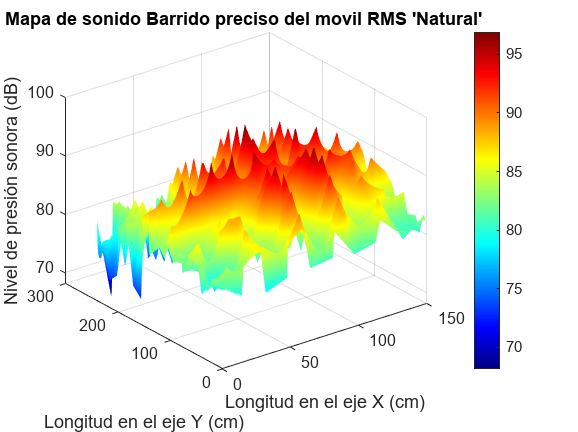

% Interpolar los datos (Interpolación natural) con el mallado
Zq = griddata(salida(1:end-1,1), salida(1:end-1,2), A_db, Xq, Yq,'natural');

figure
S = surf(Xq,Yq,Zq);

title("Mapa de sonido Barrido preciso del movil RMS 'Natural' ")
xlabel("Longitud en el eje X (cm)")
ylabel("Longitud en el eje Y (cm)")
zlabel("Nivel de presión sonora (dB)")
colorbar
shading interp
colormap(jet)

%Cargamos la imagen

altavoz2 = imread('altavoz2.jpg');

% Ajustamos al tamaño de los datos
referencia = imresize(altavoz2,[max(Yq,[],"all") max(Xq,[],"all")]);

%Creamos un nuevo mallado, con el objetivo de poder simular diferentes
%tamaños

eje_x_reducido = linspace(0,max_pos(1),20); % Se puede modificar el tamaño si se quiere simular una medida con más puntos
eje_y_reducido = linspace(0,max_pos(2),20);

[x_red ,y_red] = meshgrid(eje_x_reducido,eje_y_reducido); % Nuevo mallado

%Interpolación de los datos (se usa el método v4 ya que es el único que en los extremos da la matriz devuelve datos

Zq_red = griddata(salida(1:end-1,1), salida(1:end-1,2), A_lineal, x_red, y_red,'v4');

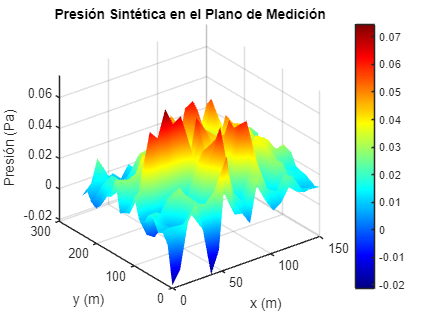

% Parámetros
zs = 0; % Plano de la fuente
zh = 0.029; % Plano de medición

X = Xq;
Y = Yq;

% Coordenadas de la fuente
xs = 0;
ys = 0;

% Representar los datos medidos de presión en 3D
figure;
surf(x_red, y_red, (Zq_red));
title('Presión Sintética en el Plano de Medición');
xlabel('x (m)');
ylabel('y (m)');
zlabel('Presión (Pa)')
colormap("jet")
shading interp
colorbar;

Zq = Zq_red;

% Parámetros conocidos
P = Zq; % matriz de presión
frec = 4000; % Frecuencia en Hz
c = 343; % Velocidad del sonido en m/s
dx = max(distancia_puntos)/1000; % Espaciado en x en metros
dy = dx; % Espaciado en y en metros
lx = max_pos(1)/1000;
ly = max_pos(2)/1000;
fs = 44100; % Frecuencia de muestreo

[M, N] = size(P);

% Parámetros adicionales
ro = 1.185; % Densidad del aire en kg/m^3
w = 2 * pi * frec; % Frecuencia angular
k = 2 * pi * frec / c; % Número de onda

zh = 0.029; % Plano de medida
zs = 0; % Plano de la fuente
d = zs - zh; % Distancia de retropropagación

dx = lx/M; % Espaciado entre los puntos de medida en el eje X
dy = ly/N; % Espaciado entre los puntos de medida en el eje Y

m=M;
n=N;

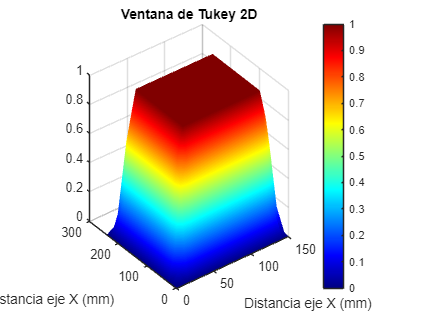

%Filtro en espacio real
% Parámetro de la ventana de Tukey
r = 0.3; % Proporción de la ventana que tiene una transición suave

% Generar ventanas de Tukey para cada dimensión
tukey_x = tukeywin(M, r);
tukey_y = tukeywin(N, r);

% Crear ventana 2D multiplicando las ventanas 1D
window_2D = tukey_x * tukey_y';

% Visualizar la ventana 2D
figure;
surf(eje_x_reducido,eje_y_reducido,window_2D);
xlabel('Distancia eje X (mm)');
ylabel('Distancia eje X (mm)');
title('Ventana de Tukey 2D');
shading interp
colormap("jet")
colorbar;

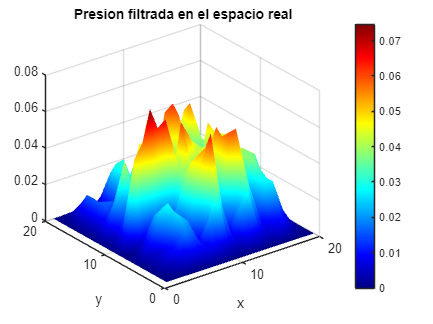

%Filtrado espacial

Ptotalbien=P.*window_2D;

figure;
surf(abs(Ptotalbien));
xlabel('x');
ylabel('y');
title('Presion filtrada en el espacio real');
colormap(jet)
shading interp
colorbar;

% Cálculo del tamaño del padding de ceros

Lx =2^(floor(log10(m)/log10(2)) + 1);%calculo la potencia de 2 mas cercana a m
Ly =2^(floor(log10(n)/log10(2)) + 1);%calculo la potencia de 2 mas cercana a n

%Nuevas dimensiones con el padding
Lx=Ly;
L=Ly;
lx=L*dx;
ly=L*dy; 

%se añaden ceros en x e y
Ptotalbien =[zeros(n,ceil((Ly-m)/2)) Ptotalbien zeros(n,ceil((Ly-m)/2))];
Ptotalbien =[zeros(ceil((Ly-n)/2),Ly); Ptotalbien; zeros(ceil((Ly-n)/2),Ly)];

%Si el numero de datos del mallado es impar, descomentar la siguiente línea

%Ptotalbien = Ptotalbien(1:end-1,1:end-1);

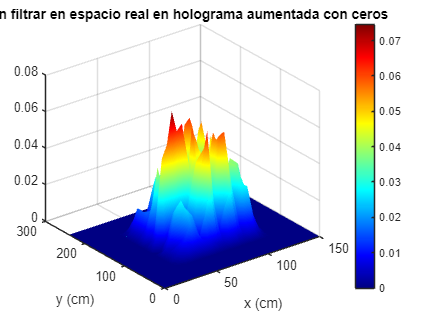

% Representación del plano de presion con el padding de ceros

figure;

X_extendida = linspace(0,max_pos(1),Lx);
Y_extendida = linspace(0,max_pos(2),Ly);
surf(X_extendida,Y_extendida,abs(Ptotalbien))
xlabel('x (cm)')
ylabel('y (cm)')
title('P sin filtrar en espacio real en holograma aumentada con ceros ')
shading interp
colormap(jet)
colorbar

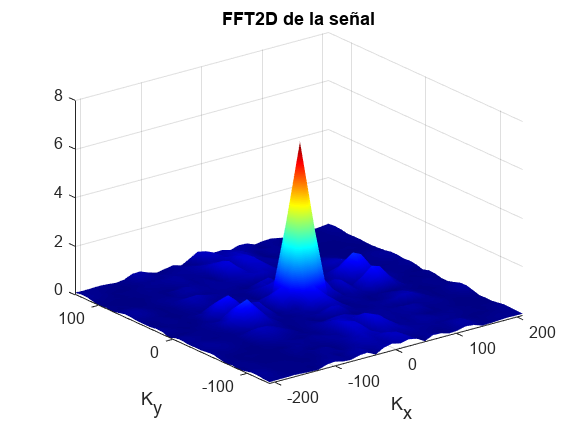

%CALCULO DE LA FFT2D
%FFT2Dxy, en x e y,en dominio de la frecuencia para obtener espectro angular en el holograma Pf2(kx,ky)
Pf2=fftshift(fft2(Ptotalbien));% esta es la FFT2Dxy,espectro angular en el holograma Pf2(kx,ky)

% Crear vectores de números de onda kx y ky
[ejex, ejey] = size(Ptotalbien);
kx1 = linspace(-pi/(2*dx), pi/(2*dx), Lx);
ky1 = linspace(-pi/(2*dy), pi/(2*dy), Ly);

%Representación de la Transformada de Fourier en 2D
figure
surf(kx1,ky1,(abs(Pf2)))
xlabel("K_x")
ylabel("K_y")
shading interp
colormap("jet")
title('FFT2D de la señal')

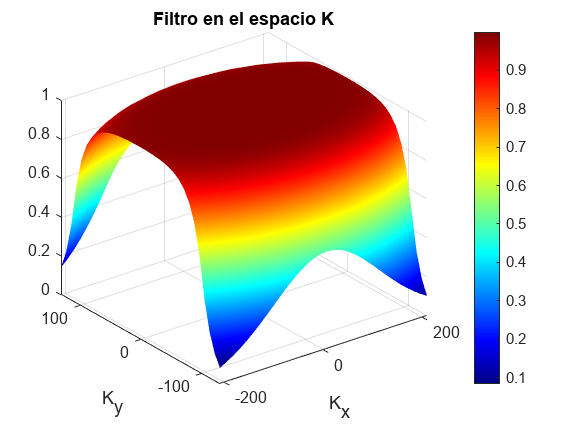

%Calculo de la funcion filtro en el espacio K
a=0.1;
L = Ly;
x=(-(L-0)/2):((L-2)/2);
y=(-(L-0)/2):((L-2)/2);

for e=0:L-1;
    for r=0:L-1;
        kx=pi*(e-L/2)/lx;
        ky=pi*(r-L/2)/ly;
        kc=0.5*pi/dx;
        kr=sqrt(kx^2+ky^2);
        if kr<=kc
            W(e+1,r+1)=1-(exp((kr/kc-1)/a))/2;
        else
            W(e+1,r+1)=(exp((1-kr/kc)/a))/2;
        end
    end
end

figure
surf(kx1,ky1,W)
xlabel("K_x")
ylabel("K_y")
shading interp
colormap("jet")
title('Filtro en el espacio K')
colorbar

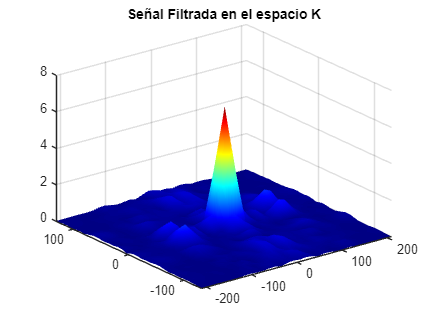

% Filtrado en el espacio K
Pf2filtrada=Pf2.*W;

figure
surf(kx1,ky1,abs((Pf2filtrada)))
title('Señal Filtrada en el espacio K')
shading interp
colormap("jet")

k=2*pi*(frec/c);

%distancia a la que se propaga
d=(zs-zh) %distancia a la que se propaga hacia atras(poner el signo -), d=-zh

d = -0.0290

ro=1.185

ro = 1.1850

w=2*pi*frec

w = 2.5133e+04

cte=1/(2*w*ro)

cte = 1.6788e-05

%kx=pi*x/lx en lugar de 2pi*x/lx porque sólo se pueden resolver componentes por
%encima de los números de onda Nyquist que son kxmax/2 y kymax/2.
%calculo de la funcion de Green para retropropagar
for p=0:L-1
    for q=0:L-1
        kx=pi*(p-L/2)/ly;
        ky=pi*(q-L/2)/lx;
        if ((kx)^2+(ky)^2)<=k^2
            kz =(k^2- (kx)^2 - (ky)^2);
            G(p +1,q +1) = exp(-1i*d*sqrt(kz));%ondas planas
        else
            kz =((kx)^2+(ky)^2-k^2);
            G(p +1,q +1) = exp(-d*sqrt(kz));%ondas evanescentes
        end
    kxx(p +1,q +1)=kx;
    kyy(p +1,q +1)=ky;
    kzz(p +1,q +1)=kz;
    end
end

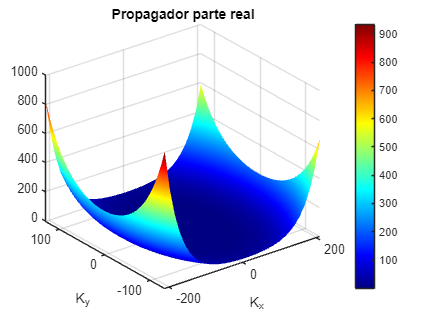

%Representación del propagador
figure

surf(kx1,ky1,abs(G))
xlabel("K_x")
ylabel("K_y")
title('Propagador parte real')
colormap("jet")
shading interp
colorbar

% Se multiplica la presion en el espacio k por el propagador

presionk=Pf2filtrada.*(G);

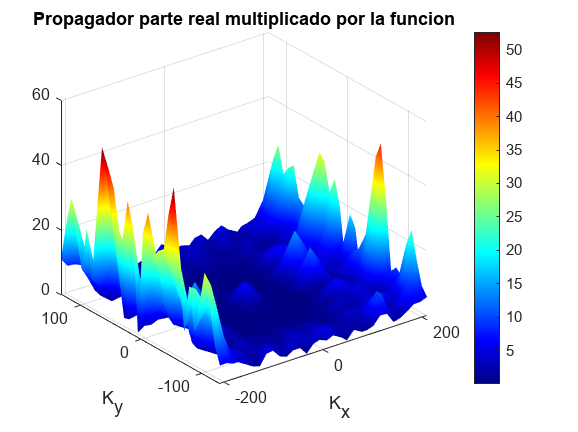

% Representación de la señal por el propagador
figure

surf(kx1,ky1,abs(presionk))
xlabel("K_x")
ylabel("K_y")
title('Propagador parte real multiplicado por la funcion')
colormap("jet")
shading interp
colorbar

% Para volver al espacio real se desplaza la presion en k para centrar la imagen y se le aplica la transformada de Fourier inversa 2D
Pftereal=(ifft2(fftshift(presionk)));

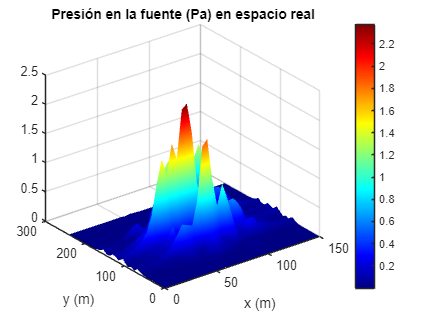

% Representación del plano de presión en la fuente
figure;
x=1:L;
y=1:L;
surf(X_extendida,Y_extendida,abs(Pftereal))
xlabel('x (m)')
ylabel('y (m)')
title('Presión en la fuente (Pa) en espacio real')
colormap("jet")
shading interp
colorbar

% Calculo de otras características físicas del sonido
Vxfte=(ifft2(fftshift(kxx.*presionk)))/(w*ro);%velocidad en eje x, kx es una matriz q tiene filas iguales 
Vyfte=(ifft2(fftshift(kyy.*presionk)))/(w*ro);%velocidad en eje y, ky es una matriz q tiene columnas iguales
Vzfte=(ifft2(fftshift(kzz.*presionk)))/(w*ro);%velocidad en eje z, (m/s)
%intensidad activa W/m2
Ix=0.5*real(Pftereal.*conj(Vxfte));
Iy=0.5*real(Pftereal.*conj(Vyfte));
Iz=0.5*real(Pftereal.*conj(Vzfte));
%intensidad reactiva
Qx=0.5*imag(Pftereal.*conj(Vxfte));
Qy=0.5*imag(Pftereal.*conj(Vyfte));
Qz=0.5*imag(Pftereal.*conj(Vzfte));
%Nivel de intensidad activa en dB
LIx=10*log10(Ix/1e-12);
LIy=10*log10(Iy/1e-12);
LIz=10*log10(Iz/1e-12);

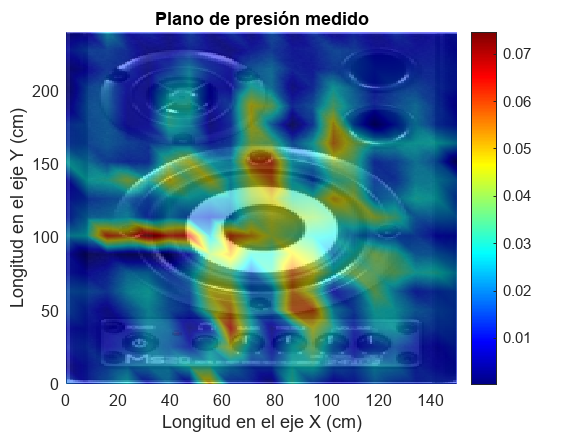

% Representación del mapa de presión medido
figure
Zq_red_imag = griddata(salida(1:end-1,1), salida(1:end-1,2), A_lineal, x_red, y_red,'v4');
p_plano_medida=surf(x_red, y_red,abs(Zq_red_imag));

title("Plano de presión medido")
xlabel("Longitud en el eje X (cm)")
ylabel("Longitud en el eje Y (cm)")
zlabel("Nivel de presión sonora (Pa)")
colorbar
shading interp
colormap(jet)
p_plano_medida.FaceAlpha = 0.5;
grid on
view([0 90])
xlim([0 max_pos(1)])
ylim([0 max_pos(2)])
hold on

image(flip(referencia))

hold off

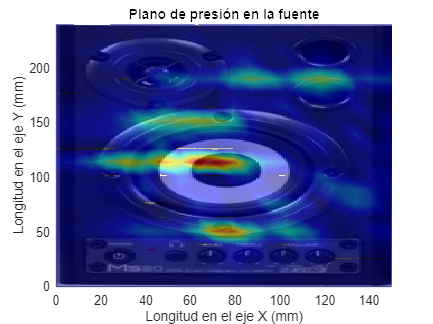

%Representación del plano de presión en la fuente

figure

Pftereal_imag = Pftereal((length(Pftereal)-length(Zq_red_imag))/2:length(Pftereal)-(length(Pftereal)-length(Zq_red_imag))/2-1 ,(length(Pftereal)-length(Zq_red_imag))/2-1:length(Pftereal)-(length(Pftereal)-length(Zq_red_imag))/2-2);

p_fuente=surf(x_red, y_red,abs(Pftereal_imag));

title("Plano de presión en la fuente")
xlabel("Longitud en el eje X (mm)")
ylabel("Longitud en el eje Y (mm)")
shading interp
colormap(jet)
p_fuente.FaceAlpha = 0.5;
grid on
view([0 90])
xlim([0 max_pos(1)])
ylim([0 max_pos(2)])
hold on

image(flip(referencia))

hold off

% Propagación en el campo lejano

% %distancia a la que se propaga
dislej=0.5;%distancia a la que se quiere propagar hacia delante a partir de la superficie de la fuente
ro=1.185;
w=2*pi*frec;
cte=1/(2*w*ro);
%calculo de la funcion de Green
for p=0:L-1;
    for q=0:L-1;
        kx=pi*(p-L/2)/lx;
        ky=pi*(q-L/2)/ly;
        if ((kx)^2+(ky)^2)<=k^2;
            kz =((k)^2- (kx)^2 - (ky)^2);
            Gdislej(p +1,q +1) = exp(-i*dislej*sqrt(kz));%ondas planas
        else
            kz =((kx)^2+(ky)^2-k^2);
            Gdislej(p +1,q +1) = exp(-dislej*sqrt(kz));%ondas evanescentes
        end
    kxxdislej(p +1,q +1)=kx;
    kyydislej(p +1,q +1)=ky;
    kzzdislej(p +1,q +1)=kz;
    end
end 

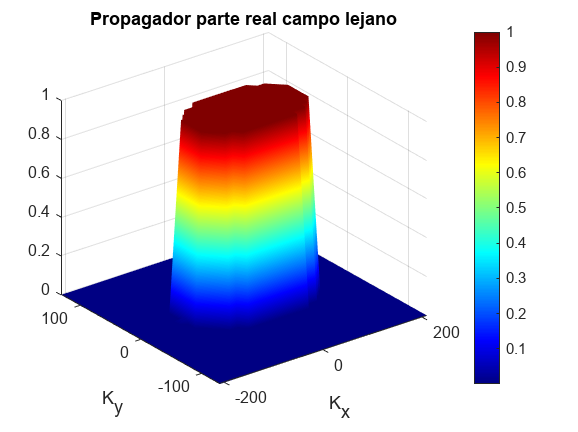

% Representación del propagador en campo lejano
figure
surf(kx1,ky1,abs(Gdislej))
title('Propagador parte real campo lejano')
xlabel("K_x")
ylabel("K_y")
colorbar
shading interp
colormap(jet)

% Multiplicación del propagador con el plano de presión

Pdislej=Pf2filtrada.*Gdislej;%valores en superficie fte x propagador hacia adelante

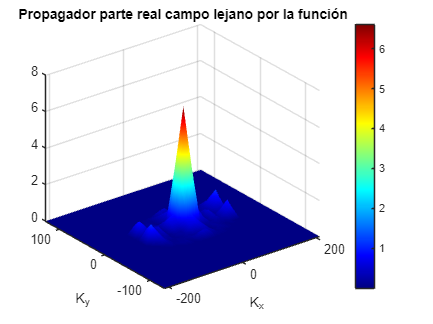

% Representación del plano de presión multiplicado por el propagador
figure
surf(kx1,ky1,abs(Pdislej))
title('Propagador parte real campo lejano por la función')
xlabel("K_x")
ylabel("K_y")
colorbar
shading interp
colormap(jet)


Pdislejreal=(ifft2(fftshift(Pdislej)));

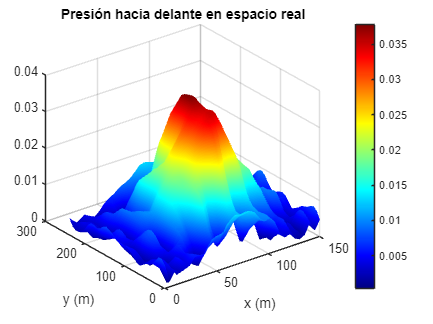

% Representación del plano de presión a una distancia d
figure;
x=1:L;
y=1:L;
surf(X_extendida,Y_extendida,abs(Pdislejreal))
xlabel('x (m)')
ylabel('y (m)')
title('Presión hacia delante en espacio real')
colorbar
shading interp
colormap(jet)


Vxftedislej=ifft2(fftshift(kxxdislej.*Pdislej))/w*ro;%kx es una matriz q tiene filas iguales
Vyftedislej=ifft2(fftshift(kyydislej.*Pdislej))/w*ro;%ky es una matriz q tiene columnas iguales
Vzftedislej=ifft2(fftshift(kzzdislej.*Pdislej))/w*ro;%.* 

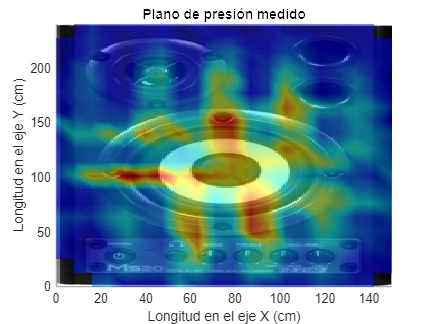

% Representación del plano de presión medido en el espacio real

figure
Zq_red_imag = griddata(salida(1:end-1,1), salida(1:end-1,2), A_lineal, x_red, y_red,'natural');
p_plano_medida=surf(x_red, y_red,abs(Zq_red_imag));

title("Plano de presión medido")
xlabel("Longitud en el eje X (cm)")
ylabel("Longitud en el eje Y (cm)")
shading interp
colormap(jet)
p_plano_medida.FaceAlpha = 0.5;
grid on
view([0 90])
xlim([0 max_pos(1)])
ylim([0 max_pos(2)])
hold on

image(flip(referencia))

hold off

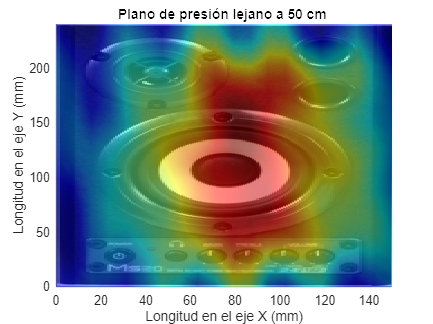

% Representación del plano de presión a una distancia d en el espacio real

figure

Pftereal_imag_lej = Pdislejreal((length(Pdislejreal)-length(Zq_red_imag))/2+1:length(Pdislejreal)-(length(Pdislejreal)-length(Zq_red_imag))/2 ,(length(Pdislejreal)-length(Zq_red_imag))/2:length(Pdislejreal)-(length(Pdislejreal)-length(Zq_red_imag))/2-1);

p_fuente=surf(x_red, y_red,abs(Pftereal_imag_lej));

% S.FaceAlpha = 0.5;
% view([0 270])
title("Plano de presión lejano a 50 cm ")
xlabel("Longitud en el eje X (mm)")
ylabel("Longitud en el eje Y (mm)")
shading interp
colormap(jet)
p_fuente.FaceAlpha = 0.5;
grid on
view([0 90])
xlim([0 max_pos(1)])
ylim([0 max_pos(2)])
hold on

image(flip(referencia))

hold off